MECHENG 736/730 - Assignment 1: Measuring and decoding the electroencephalogram (EEG)

Student: Gabriel Werpel Fernandes - gfer533@aucklanduni.ac.nz - UoA ID: 989055637

**Task 2:**

% Load, Extract alphaPower, betaPower, and labels from combinedData
load('combinedEEGData.mat');
alphaPower = combinedData(:, 1);
betaPower = combinedData(:, 2);
labels = combinedData(:, 3);

% Split the data into training and testing
alphaTrain = alphaPower(1:34);
betaTrain = betaPower(1:34);
alphaTest = alphaPower(35:36);
betaTest = betaPower(35:36);

% Create training and testing matrices
trainingData = [alphaTrain, betaTrain];
testingData = [alphaTest, betaTest];
group = labels(1:34); % labels for the training data

% Use MATLAB's classify function to get the linear decision boundary
class = classify(testingData, trainingData, group, 'linear');

% Train a linear discriminant analysis classifier
MdlLinear = fitcdiscr(trainingData, group);

% Extract the coefficients for the linear boundary
K = MdlLinear.Coeffs(1,2).Const;  
L = MdlLinear.Coeffs(1,2).Linear;

% Calculate the slope and intercept of the linear boundary
f = @(x1,x2) K + L(1)*x1 + L(2)*x2;

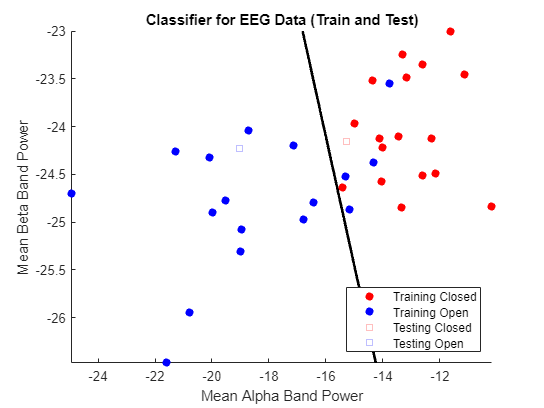

% Plotting
figure;

% Plot training data
scatter(alphaTrain(labels(1:34) == 0), betaTrain(labels(1:34) == 0), 'ro', 'filled'); % Eyes closed
hold on;
scatter(alphaTrain(labels(1:34) == 1), betaTrain(labels(1:34) == 1), 'bo', 'filled'); % Eyes open

% Plot testing data with different marker
scatter(alphaTest(labels(35:36) == 0), betaTest(labels(35:36) == 0), 'rs'); % Eyes closed
scatter(alphaTest(labels(35:36) == 1), betaTest(labels(35:36) == 1), 'bs'); % Eyes open

% Plot intercept of the linear boundary
h2 = ezplot(f, [min(alphaPower) max(alphaPower) min(betaPower) max(betaPower)]); 
set(h2,'Color','k','LineWidth',2)

xlabel('Mean Alpha Band Power');
ylabel('Mean Beta Band Power');
legend('Training Closed', 'Training Open', 'Testing Closed', 'Testing Open','Location', 'southeast');
title('Classifier for EEG Data (Train and Test)');